## **Matlab kode/beskrivelser til ADSB projekt 2021**

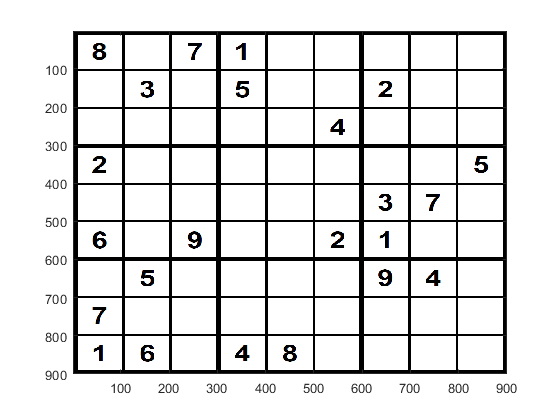

clear; close all;

x = 'sudoku_input.png' ;
sudokuBW=imread(x);
imagesc(sudokuBW)

actuelSize = size(sudokuBW)

actuelSize =    900   900     3


originalSize = 450;
scaleFactor = originalSize/actuelSize(1)

scaleFactor =           0.5


sudokuBW = imresize(sudokuBW,scaleFactor);

size(sudokuBW)

ans =    450   450     3


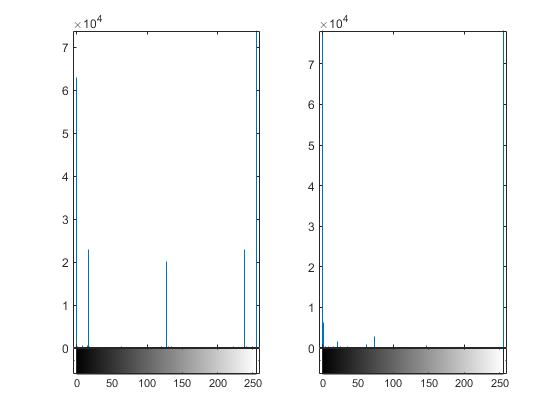

figure
hold on

subplot(121)
imhist(sudokuBW)
xlim([-5 260])

sudokuBW = imsharpen(sudokuBW,'Radius',5,'Amount',2);

subplot(122)
imhist(sudokuBW)
xlim([-5 260])

hold off

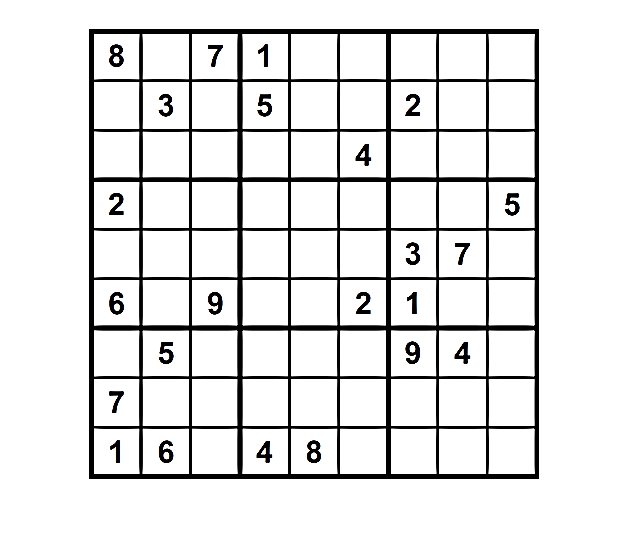

figure
imshow(sudokuBW)


data = sudokuBW

data = 450×450×3 uint8 array
data(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

imChange2 = rgb2gray(data);
imChange3 = imbinarize(imChange2,0.65);
imChange4 = bwareaopen(imChange3,50);
felt_data = regionprops(imChange4, 'BoundingBox', 'Centroid')

felt_data = 81×1 struct array with fields:
    Centroid
    BoundingBox


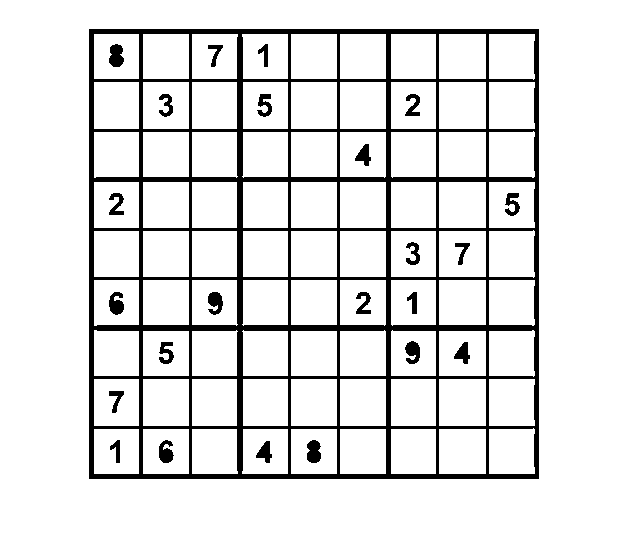

figure
imshow(imChange4);

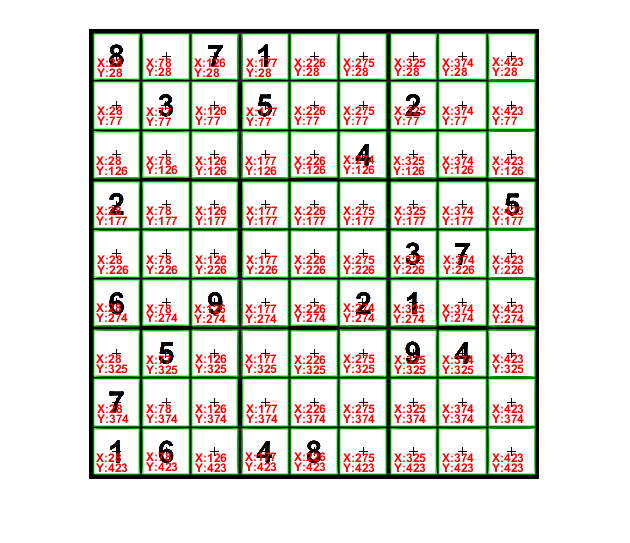

%overlay/visualisering af koordinater   
imshow(sudokuBW);
    hold on
    for object = 1:length(felt_data)
        sudoku_BBox = felt_data(object).BoundingBox;
        Sudoku_C = felt_data(object).Centroid;
        
        rectangle('Position',sudoku_BBox,'EdgeColor','g','LineWidth',0.8)
        plot(Sudoku_C(1),Sudoku_C(2), '-black+')
       
        textX=text(Sudoku_C(1)-20,Sudoku_C(2)+5, strcat('X:', num2str(round(Sudoku_C(1)))));
        textY=text(Sudoku_C(1)-20,Sudoku_C(2)+15, strcat('Y:', num2str(round(Sudoku_C(2)))));
        set(textX, 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
        set(textY, 'FontWeight', 'bold', 'FontSize', 9, 'Color', 'red');
    end
    hold off

format short G
felt_data

felt_data = 81×1 struct array with fields:
    Centroid
    BoundingBox


%segmentering med bwboundaries
boundaries=bwboundaries(imChange4);
Image = {}


Image =

  0×0 empty cell array



for i = 1:81
    [xmin, ymin]=min(boundaries{i,1}); 
    [xmax, ymax]=max(boundaries{i,1});
    Image{end+1,1}=imChange2(xmin(1,1):xmax(1,1),xmin(1,2):xmax(1,2));
end
Image

Image = 81×1 cell array
    {45×45 uint8}
    {47×45 uint8}
    {46×45 uint8}
    {46×45 uint8}
    {46×45 uint8}
    {46×45 uint8}
    {46×45 uint8}
    {47×45 uint8}
    {45×45 uint8}
    {45×46 uint8}
    {47×46 uint8}
    {45×46 uint8}
    {46×46 uint8}
    {46×46 uint8}
    {45×46 uint8}
    {45×46 uint8}


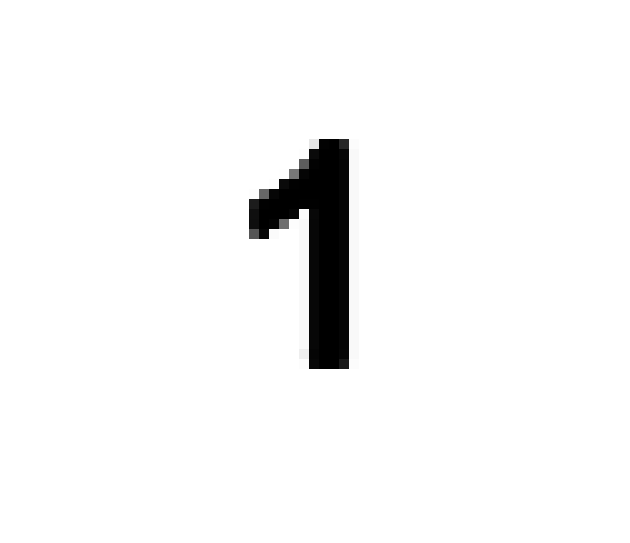

%eksempeludskrift af felt i række 9, kolonne 1;

imshow(Image{9,1})

%imwrite anvendes til at gemme talprofiler fra 1 til 9
%imwrite(Image{9,1}, 'x.jpg');

%her findes tallene på sudokupladen
grid = correlationImage(Image);
grid 

grid =      8     0     7     1     0     0     0     0     0
     0     3     0     0     0     0     2     0     0
     0     0     0     0     0     4     0     0     0
     2     0     0     0     0     0     0     0     5
     0     0     0     4     0     0     3     7     0
     6     0     9     5     0     2     1     0     0
     0     5     0     0     0     0     9     4     0
     7     0     0     0     0     0     0     0     0
     1     6     0     0     8     0     0     0     0


%her findes resultaterne ud fra grid
grid_solved = sudoku(grid);
grid_solved

grid_solved = grid_solved(:,:,1) =

     8     2     7     1     5     9     4     3     6
     4     3     5     6     7     8     2     1     9
     9     1     6     3     2     4     8     5     7
     2     4     3     8     1     7     6     9     5
     5     8     1     4     9     6     3     7     2
     6     7     9     5     3     2     1     8     4
     3     5     2     7     6     1     9     4     8
     7     9     8     2     4     3     5     6     1
     1     6     4     9     8     5     7     2     3


grid_solved(:,:,2) =

     8     2     7     1     5     9     4     3     6
     4     3     5     7     6     8     2     1     9
     9     1     6     3     2     4     8     5     7
     2     4     3     8     1     7     6     9     5
     5     8     1     4     9     6     3     7     2
     6     7     9     5     3     2     1     8     4
     3     5     2     6     7     1     9     4     8
     7     9     8     2     4     3     5     6     1
     

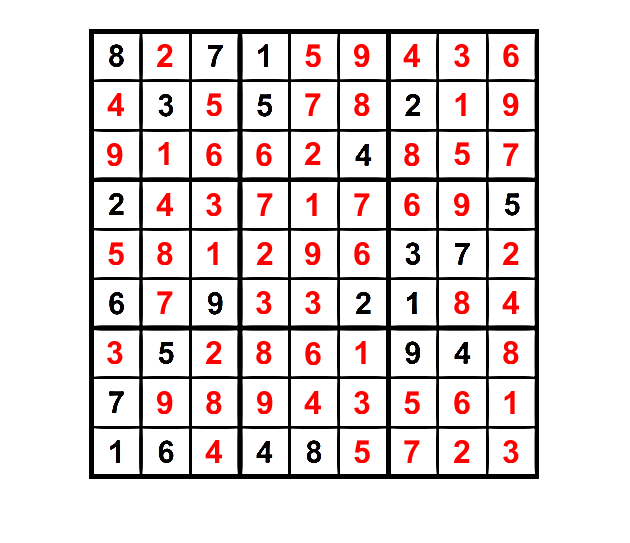

Index exceeds the number of array elements (81).

%overlay laves til at vise resultater
grid_overlay = grid_solved - grid; 
imshow(sudokuBW);

hold on
 for j = 1: numel(grid_overlay)
     if (grid_overlay(j)~= 0)
        Sudoku_C = felt_data(j).Centroid;
        textX=text(Sudoku_C(1)-10,Sudoku_C(2)-2, strcat(num2str(round(grid_overlay(j)))));
        set(textX, 'FontWeight', 'bold', 'FontSize', 24, 'Color', 'red');
     end
 
 end

hold off